% 求出x方向扩展距离和y方向扩展距离的映射表 shift
r = 10  % 覆盖半径

r = 10


a = zeros(2*r+1)

a =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     

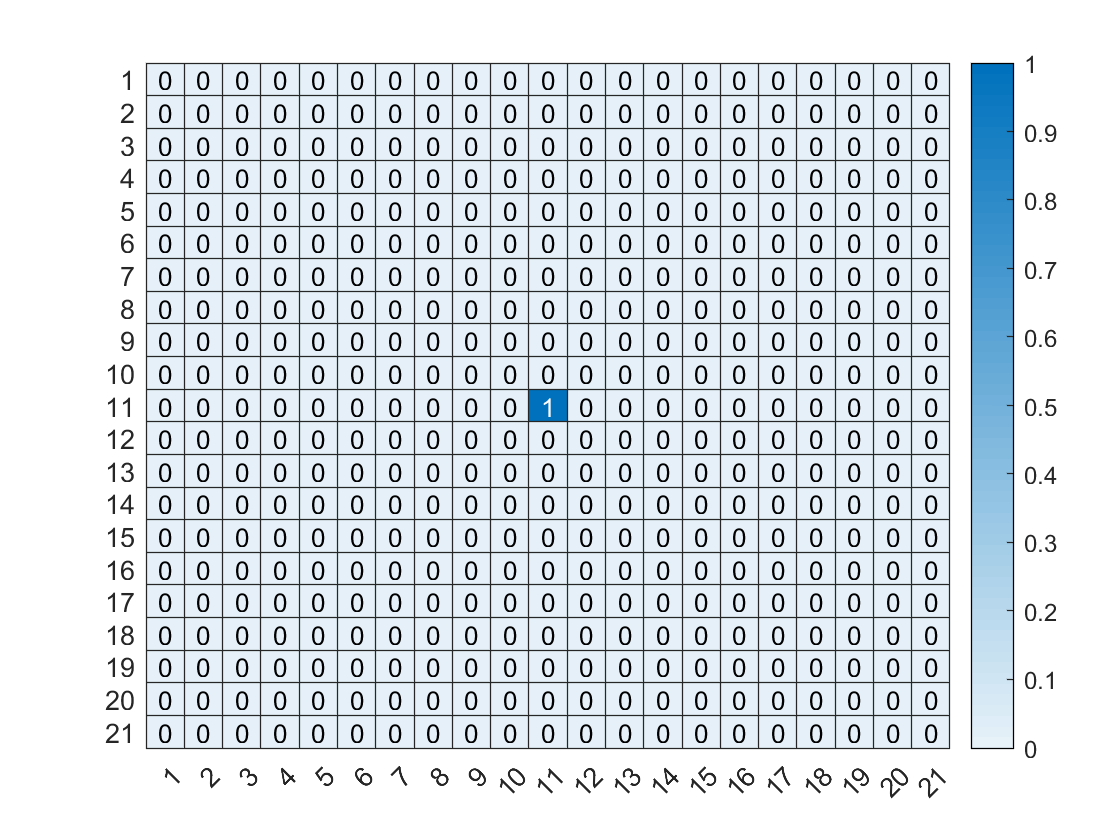

b = a;
b(r+1,r+1) = 1;
heatmap(b)

shift = zeros(1,r+1)  % 映射表

shift =      0     0     0     0     0     0     0     0     0     0     0


for i = 1:size(a,1)
    for j = 1:size(a,1)
        if (i-r-1)^2+(j-r-1)^2 <= r^2
            a(i,j) = 1;
        end
    end
end

% 求出x方向扩展距离和y方向扩展距离的映射表
for i = 1:r+1
    shift(i) = sum(a(r+i,1:r));
end
shift

shift =     10     9     9     9     9     8     8     7     6     4     0


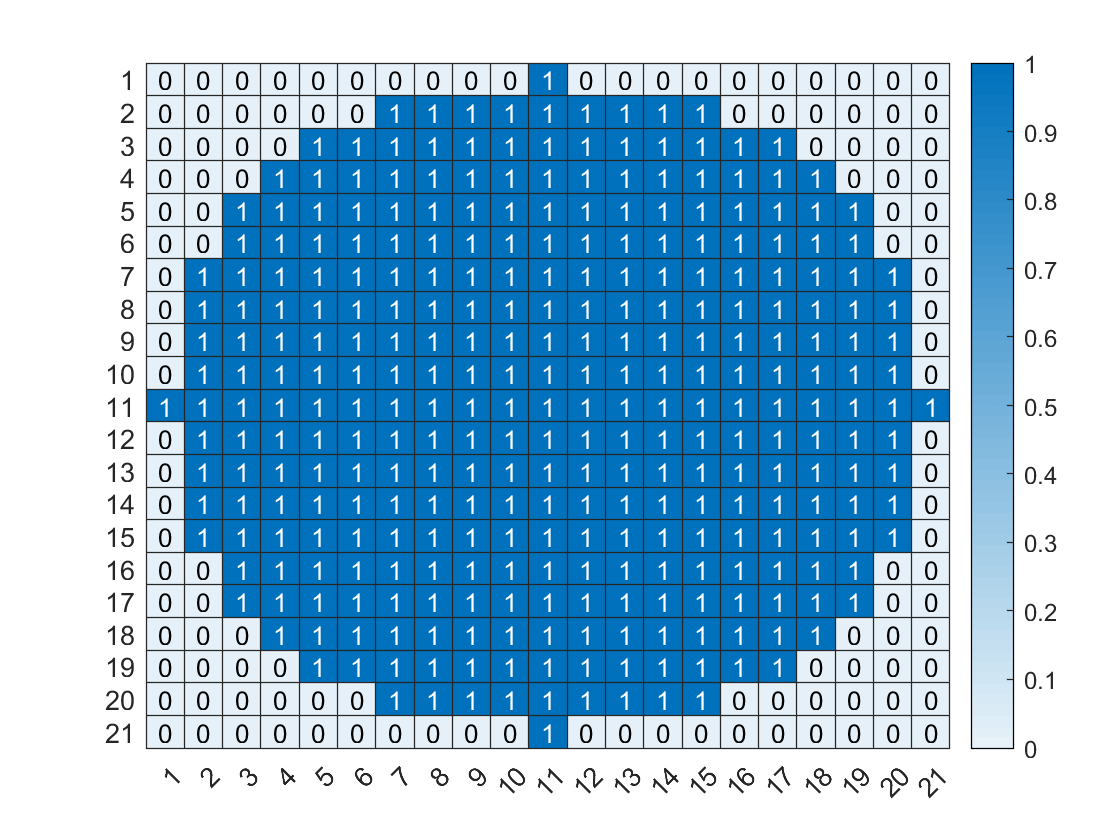

heatmap(a)

shift14 = [14    13    13    13    13    13    12    12    11    10     9     8     7     5     0];
shift10 = [10     9     9     9     9     8     8     7     6     4     0];
shift20 = [20    19    19    19    19    19    19    18    18    17    17    16    16    15    14    13    12    10     8     6     0];
shift30 = [30    29    29    29    29    29    29    29    28    28    28    27    27    27    26    25    25    24    24    23    22    21    20    19    18    16    14    13    10     7     0];
